# Lights marks

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Create povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Standard textures

%     DMFWood6
%     NBglass            (Norm Bowler)
%     NBoldglass         (Norm Bowler)
%     NBwinebottle       (Norm Bowler)
%     NBbeerbottle       (Norm Bowler)
%     Ruby_Glass         (after Norm Bowler)
%     Dark_Green_Glass   (after Norm Bowler)
%     Yellow_Glass       (after Norm Bowler)
%     Orange_Glass       (after Norm Bowler)
%     Vicks_Bottle_Glass (after Norm Bowler)
%     Soft_Silver        (Dan Farmer)
%     New_Penny          (Dan Farmer)
%     Tinny_Brass        (Dan Farmer)
%     Gold_Nugget        (Dan Farmer)
%     Aluminum           (Dan Farmer)
%     Bright_Bronze      (Dan Farmer)
%     Lightening1        (Dan Farmer)
%     Lightening2        (Dan Farmer)
%     Brushed_Aluminum   (Dan Farmer)
%     Starfield          (Jeff Burton )
%     Shadow_Clouds      (Bill Pulver)

#### Create scene

pl.scene_begin('scene_file', 'lights.pov', 'image_file', 'lights.png');
    pl.include("shapes");
    pl.global_settings("assumed_gamma 1");
    
    pl.camera('angle', 25, 'location', [35 20 19], 'look_at', [0 1 3], 'type', 'perspective');
    % pl.light('location', [100 200 300], 'color', [0.4 0.4 0.4]);
    pl.axis('length', [10 10 10]);
    
    % Axis planes
    tex_plane_red   = pl.declare("tex_plane_red",   pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    tex_plane_green = pl.declare("tex_plane_green", pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    tex_plane_blue  = pl.declare("tex_plane_blue",  pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));

    pl.plane('normal', [1,0,0], 'distance', 0, 'texture', tex_plane_red',  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
    pl.plane('normal', [0,1,0], 'distance', 0, 'texture', tex_plane_green, 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
    pl.plane('normal', [0,0,1], 'distance', 0, 'texture', tex_plane_blue,  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
    
    % Light marks
    for y = 4:6
        pl.sphere('position', [2 y 2], 'radius', 0.4, 'texture', 'Yellow_Glass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
        g = 0.1 * y;
        pl.light('location',  [2 y 2], 'color', [0.4 g 0.4]);
    end

    for y = 4:6
        pl.sphere('position', [2 y 3], 'radius', 0.4, 'texture', 'Dark_Green_Glass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
        g = 0.1 * y;
        pl.light('location',  [2 y 3], 'color', [0.4 g 0.4]);
    end

    for y = 4:6
        pl.sphere('position', [2 y 4], 'radius', 0.4, 'texture', 'NBwinebottle', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
        g = 0.1 * y;
        pl.light('location',  [2 y 4s], 'color', [0.4 g 0.4]);
    end

pl.scene_end();

#### Render scene and show image

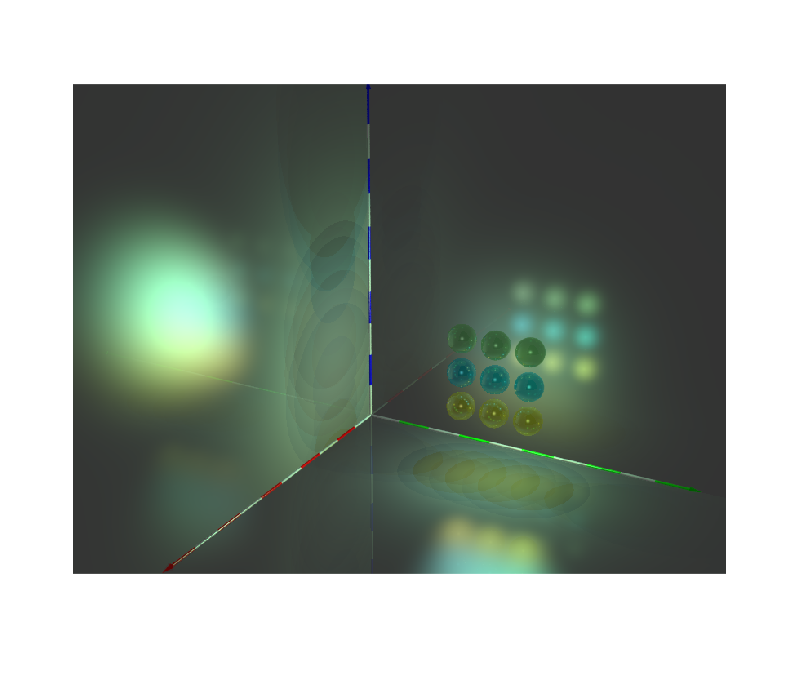

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 15.946989 seconds.
